1. wczyta zdj˛ecie z pliku,

hand_photo = imread('C:\Users\USER\Desktop\SR\hand\hand_photo.ppm')

hand_photo = 64×64×3 uint8 array
hand_photo(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   248   241   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   197  

2. dokona konwersji zdj˛ecia z formatu RGB na format YCbCr zgodnie z metod ˛a opisan ˛a w rozdziale 9.2. Uwaga. Prosz˛e nie wykorzystywac do tego celu funkcji wbudowanej ´ w srodowisko – prosz˛e wykorzysta ´ c podane równania ´ bezposrednio

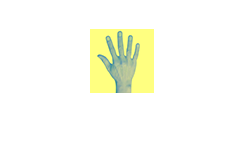

[R,G,B] = imsplit(hand_photo);

y = 0.299*R+0.587* G+0.114*B;
Cb = -0.168736*R-0.331264* G+0.5*B+128;
Cr = 0.5*R-0.418688* G-0.081312*B+128; 
YCrCb= cat(3,y,Cb,Cr);
figure
imshow(YCrCb)

3. dokona segmentacji obszaru twarzy (koloru skóry) – 9.2

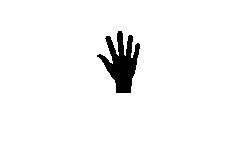

mask_p = (77<Cb & Cb<1200 & 127<Cr& Cr<140);

figure

imshow(mask_p)

4. dokona filtracji maski – kontekstowa filtracja medianowa dla obrazów binarnych (funkcja medfilt2 lub medianBlur),

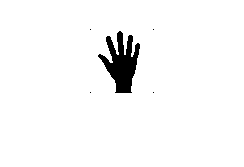

img_no_noise = medfilt2(mask_p);
figure
imshow(img_no_noise)

5. wyznaczy srodek ci˛e ´ zko ˙ sci poło ´ zenia pikseli oznaczonych jako rejon twarzy – 9.5, ˙ 

m00 = 0;
m01 = 0;
m10 = 0;
[cols, rows] = size(img_no_noise);
for i=1:cols
    for j=1:rows
        m00 = m00 + img_no_noise(i,j);
        m10 = m10 + i*img_no_noise(i,j);
        m01 = m01 + j*img_no_noise(i,j);
    end
end
Ysc = m10/m00

Ysc = 31.4754

Xsc = m01/m00

Xsc = 32.5853

6. narysuje dwie linie (pionow ˛a i poziom ˛a) przebiegaj ˛ace przez cał ˛a szerokos´c obrazu, ´

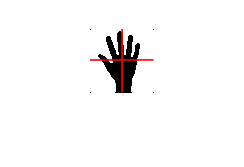


figure
imshow(img_no_noise)
line([0,64],[Ysc,Ysc],'Color','r','LineWidth',1)
line([Xsc,Xsc],[0,64],'Color','r','LineWidth',1)